# GNB Summer School 2023 - *“The Bioengineering of Sport” *

# *Extraction of Muscle Synergies in Sport: Application to the Evaluation of Chronic Ankle Instability (CAI)*

#### *September 11th 2023*

## 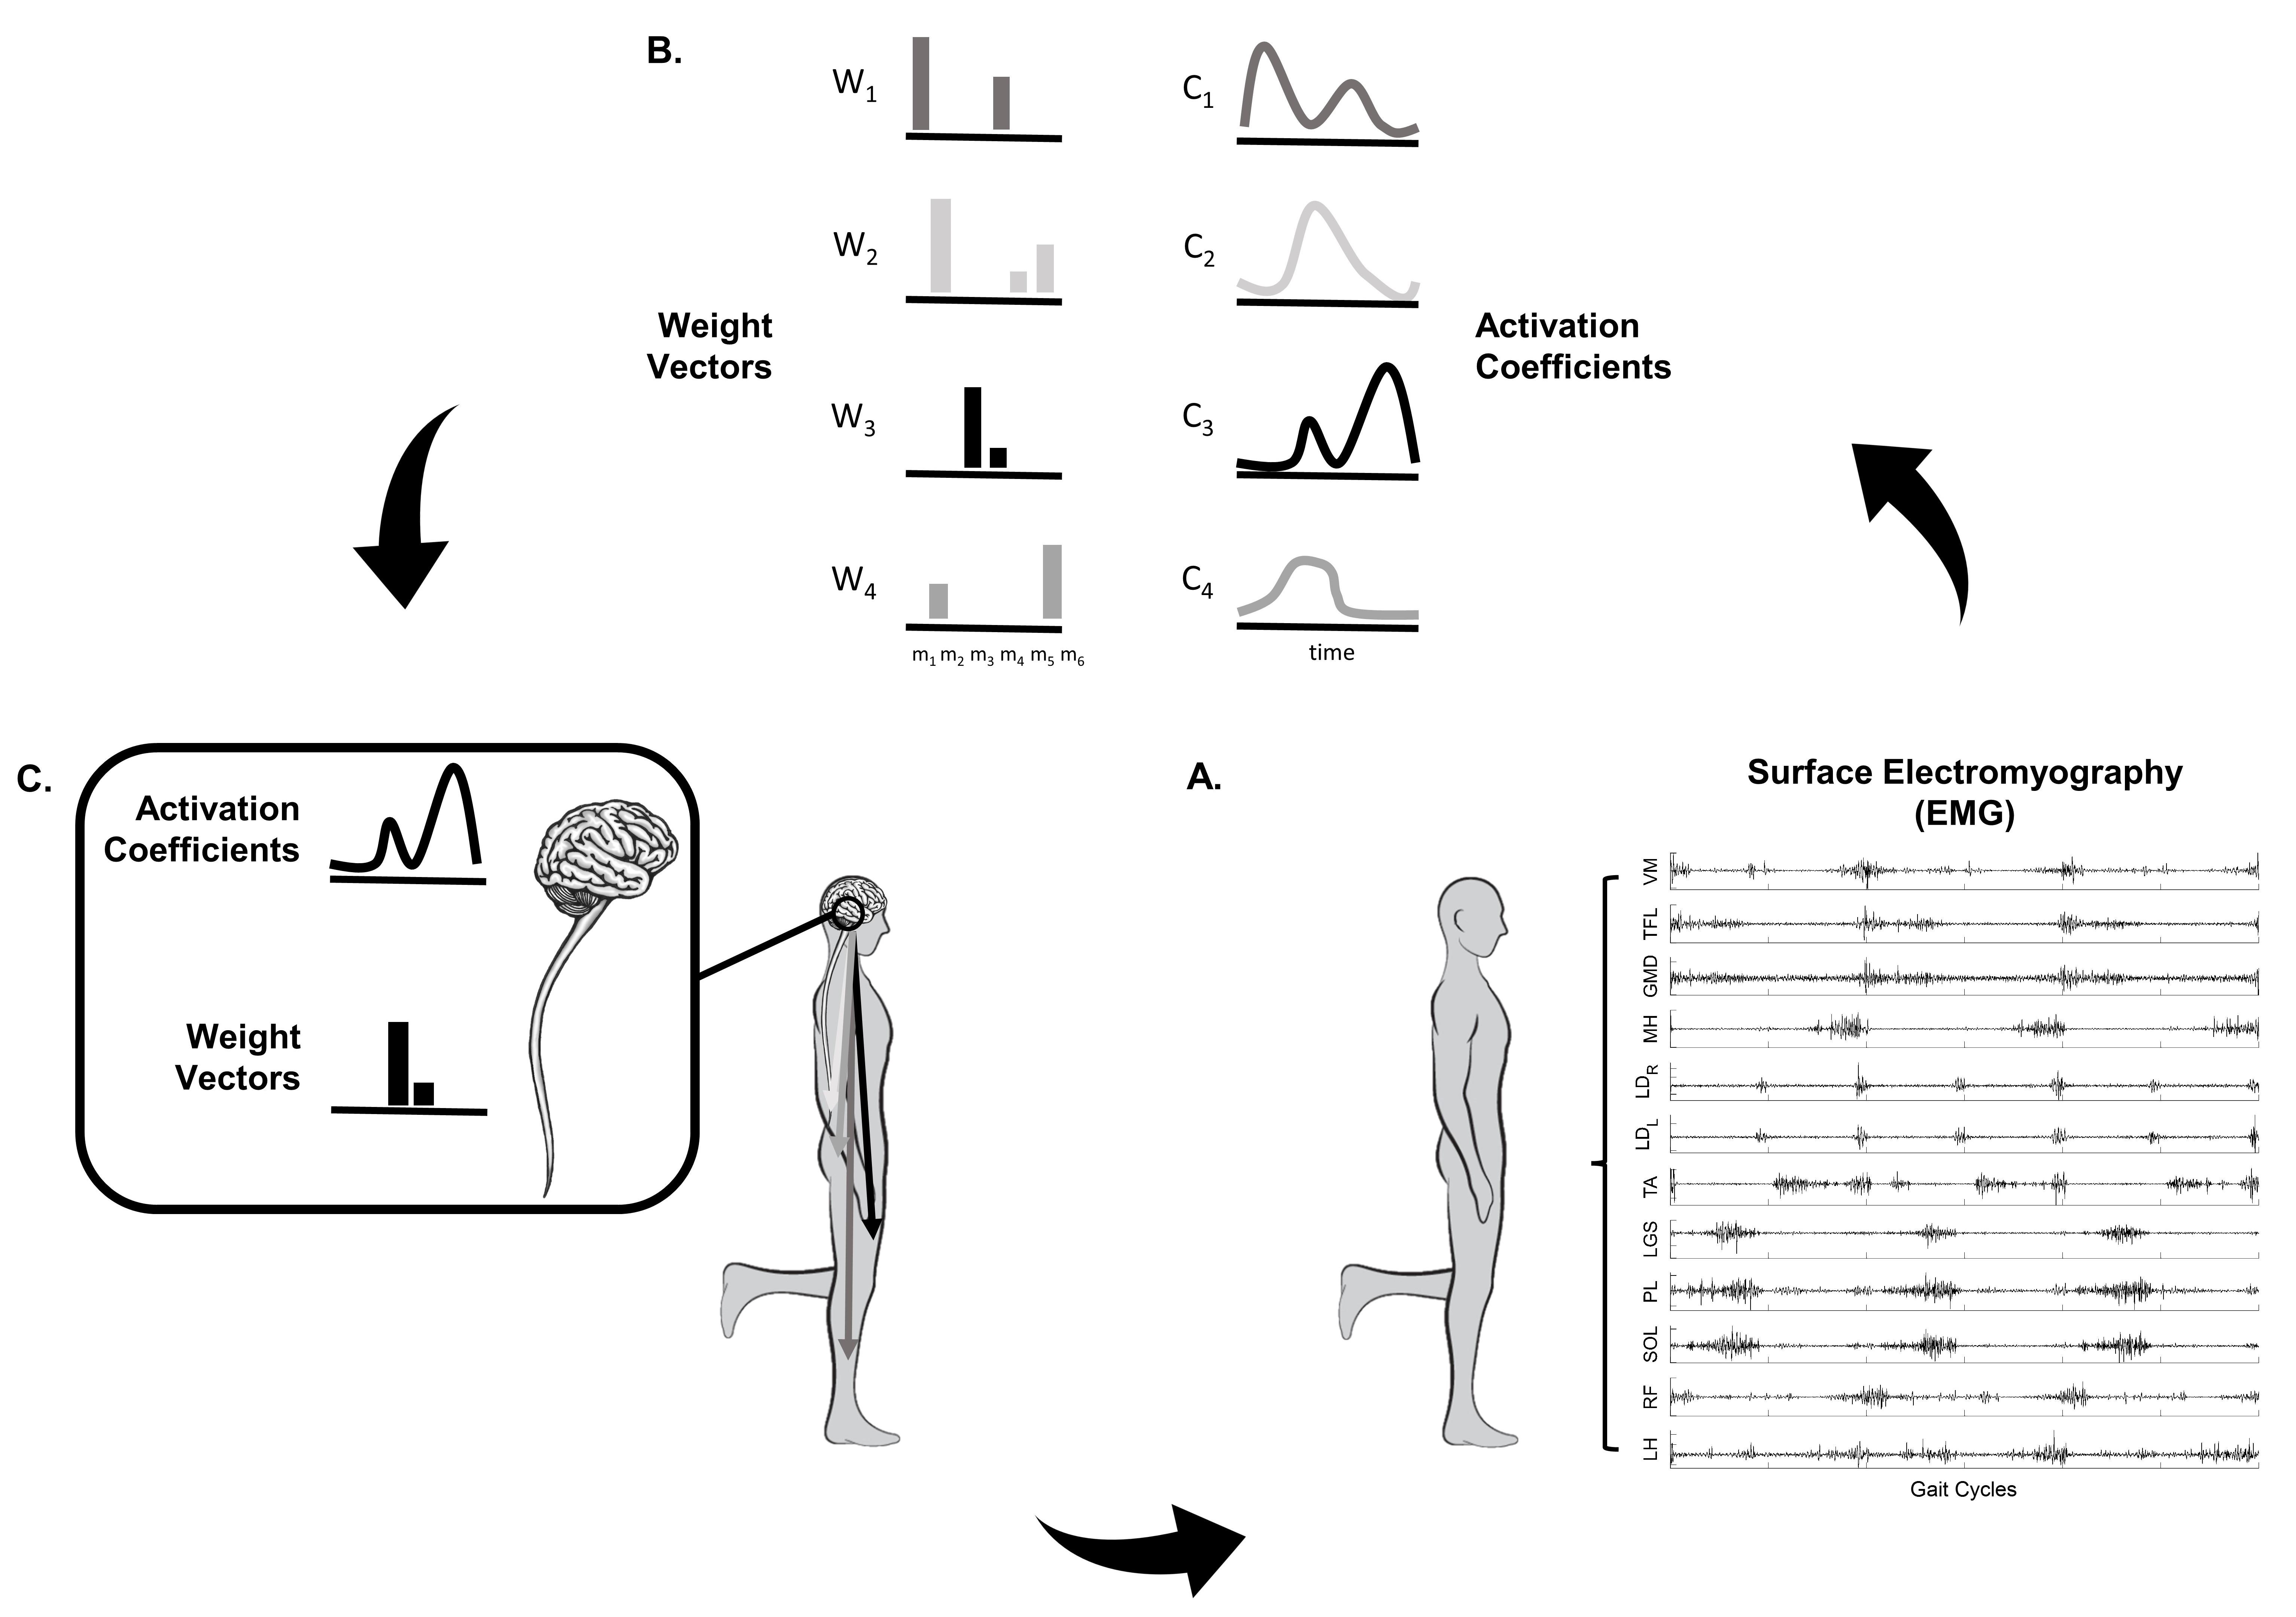

The **hands-on session** consists of the **analysis of surface EMG data **acquired from 13 muscles during **Single-Limb Stance** (SLS), to **extract muscle synergies** and **interpret them**. The team will be provided with surface EMG data from 2 subjects (one of which affected by CAI). After having evaluated the complexity of the neuromuscular control (i.e., the final number of muscle synergies needed to model the original EMG data) and the composition of the muscle synergies (i.e., the temporal and spatial components of the muscle synergies), the team should **compare the two subjects** and **establish wich one shows the best ankle stability** (to be reported on the **athlete's passport**).

*The following routines were tested on ****MATLAB© release 2023a**** and require the "****Signal Processing Toolbox****" and the "****Image Processing Toolbox****" to function.*

## A. Parameters definition

clear variables
warning off
close all
clc

#### *A.1 - Acquisition system*

opts.f_s = 1000;                             % Sampling frequency (Hz)
opts.muscles = {'PL','PB','TA','LG','SO',... % Acquired lower-limb and trunk muscles
                'VM','VL','RF','BF','ST',...
                'GM','LDI','LDC'};

#### *A.2 - Muscle synergy extraction*

opts.n_input = 1:length(opts.muscles); % Number of muscle synergies to evaluate
opts.iter =150;  % Maximum number of iterations
opts.residual = 1e-6;                  % Minimal residual value
opts.tof = 1e-6;                       % Tollerance function value
opts.reps =5;   % Maximum number of repetitions

## B. Data loading

*Read the documentation available on *[*GitHub*](https://github.com/GNB2023/BioEngSport/tree/b8007933f0b130bd03443726423b2d55c509b387/11%20Sept%202023/Extraction%20of%20muscle%20synergies%20in%20sports/Dataset)* to learn about data format and recordings. Provided data were collected at the Physical Medicine and Rehabilitation Unit of IRCCS Isituto Ortopedico Rizzoli (Bologna, Italy). For further information about experimental protocol and data recordings, refer to *[*Ghislieri et al. (2020)*](https://ieeexplore.ieee.org/document/9222277)*.*

#### *B.1 - Loading *.txt file*

*Load one of the two .txt files containing EMG data available on *[*GitHub*](https://github.com/GNB2023/BioEngSport/tree/b8007933f0b130bd03443726423b2d55c509b387/11%20Sept%202023/Extraction%20of%20muscle%20synergies%20in%20sports/Dataset)*. *

[file,path] = uigetfile('*.txt');
Data = readtable([path file]);

#### *B.2 - Raw data representation*

*Plot the raw EMG signals (sEMG) and the foot-switch signal (Fsw) used to time-segment the SLS epoch.*

figure('Units','normalized','Position',[0 0 1 1])
ax = gca;
ax.Box = 'on';
grid on
offset = 2;
win = 1:size(Data,1);
chans2plot = [4:16 3];
time = (0:(size(Data,1)-1))/opts.f_s;

pp = zeros(length(chans2plot));
hold on
for ii = 1:length(chans2plot)
    idx = chans2plot(ii);
    data = table2array(Data(win,idx)) - (ii-1)*offset;
    pp(ii) = plot(time(win),data,'linewidth',1.2);
end

ylim([-27 1])
xlim([time(win(1)) time(win(end))+.7])
xlabel('Time (s)')
ylabel('sEMG (mV)')
ax.YTick = fliplr(0 - ((1:length(chans2plot))-1)*offset);
ax.YTickLabel = fliplr([opts.muscles 'Fsw']);
line((time(win(end))+.5)*ones(1,2), [-.7,.7] - offset,'color','k','linewidth', 2);
text(time(win(end))+1, - offset, '2 mV','FontSize', 14);
line((time(win(end))+.5)*ones(1,2), [0,1] - 13*offset,'color','k','linewidth', 2);
text(time(win(end))+1, .5 - 13*offset, '1 a.u.','FontSize', 14);
set(gca,'FontSize', 14)

## C. Single-Limb Stance (SLS) Segmentation

*SLS epoch is segmented by using the Fsw signal. When both feet of the subject are in contact with the ground the Fsw signal is equal to 1, while when one foot is raised from floor the Fsw signal is equal to 0. The SLS epoch is defined as the longest 0-level of the whole Fsw signal, excluding 2 seconds of signal following the 1-to-0 transition from Double-Leg to Single-Leg Stance (DLS-to-SLS) and 2 seconds of signal preceding the 0-to-1 transition from Single-Leg to Double-Leg Stance (SLS-to-DLS).*

#### *C.1 - Detecting Double-to-Single and Single-to-Double Leg transitions*

time_delay = 2000; % Temporal delay in DLS-to-SLS (or viceversa) transition
fsw_indexes = find(diff(Data.Fsw)~=0);   % Detect foot-switch transitions (-1 = double-to-single limb transition, 
                                                                          % 1 = single-to-double limb transition)
[~,index] = max(diff(fsw_indexes));
sls_start = (fsw_indexes(index)+time_delay)/opts.f_s;  % Time instant corresponding to SLS beginning (expressed in seconds)
sls_stop = (fsw_indexes(index+1)-time_delay)/opts.f_s; % Time instant corresponding to SLS end (expressed in seconds)

See [Ghislieri et al. (2020)](https://ieeexplore.ieee.org/document/9222277) for further information about single-leg stance segmentation.

#### *C.2 - Raw data representation with the superimposition of SLS timings*

*Plot the sEMG and Fsw signals with the superimposition of the SLS timings (dotted lines).*


figure('Units','normalized','Position',[0 0 1 1])
ax = gca;
ax.Box = 'on';
grid on
offset = 2;
win = 1:size(Data,1);
chans2plot = [4:16 3];
time = (0:(size(Data,1)-1))/opts.f_s;

pp = zeros(length(chans2plot));
hold on
for ii = 1:length(chans2plot)
    idx = chans2plot(ii);
    data = table2array(Data(win,idx)) - (ii-1)*offset;
    pp(ii) = plot(time(win),data,'linewidth',1.2);
end

ylim([-27 1])
xlim([time(win(1)) time(win(end))+.7])
xlabel('Time (s)')
ylabel('sEMG (mV)')
title('Single-Limb Stance (SLS)')
ax.YTick = fliplr(0 - ((1:length(chans2plot))-1)*offset);
ax.YTickLabel = fliplr([opts.muscles 'Fsw']);
line((time(win(end))+.5)*ones(1,2), [-.7,.7] - offset,'color','k','linewidth',2);
text(time(win(end))+1, - offset, '2 mV','FontSize', 14);
line((time(win(end))+.5)*ones(1,2), [0,1] - 13*offset,'color','k','linewidth',2);
text(time(win(end))+1, .5 - 13*offset, '1 a.u.','FontSize', 14);
line([sls_start sls_start],ylim,'linestyle','--','color','k','linewidth',1.5);
line([sls_stop sls_stop],ylim,'linestyle','--','color','k','linewidth',1.5);
set(gca,'FontSize', 14)

## D. SEMG Pre-Processing

#### *D.1 - SEMG band-pass filtering*

*SEMG signals are band-pass filtered between 10 Hz and 450 Hz by means of a 4th-order, zero-lag Butterworth digital filter.*

% Initialize Band Pass Filter (BPF)
low_freq = 10;
high_freq = 450;
order = 4;
[b,a] = butter(order,[low_freq high_freq]/(opts.f_s/2),'bandpass'); % Initialize Band Pass Filter parameters
sEMG_BPF = filtfilt(b,a,table2array(Data(sls_start*opts.f_s:sls_stop*opts.f_s,chans2plot(1:end-1))));

#### *D.2 - SEMG envelope extraction*

*SEMG envelopes are extracted from the filtered sEMG data considering the default parameters for muscle synergy extraction:*

- *High-pass IIR Butterworth 8th-order filter (cut-off frequency 35 Hz);*

- *Demean sEMG signals;*

- *Full-wave rectification;*

- *Low-pass IIR Butterworth 5th-order filter (cut-off frequency 12 Hz).*

% Initialize High Pass Filter (HPF) parameters (Passband frequency 35 Hz and Order = 8)
f_hp =35/(opts.f_s/2);
order_hp = 8;
[b_hp,a_hp] = butter(order_hp,f_hp,'high');

% Initialize Low Pass Filter (LPF) parameters (Passband frequency 12 Hz and Order = 5)
f_lp =12/(opts.f_s/2);
order_lp = 5;
[b_lp,a_lp] = butter(order_lp,f_lp,'low');

% sEMG Envelope Computation
sEMG_HPF = filtfilt(b_hp,a_hp,sEMG_BPF); % HPF Butterworth
sEMG_HPF_demean = sEMG_HPF - mean(sEMG_HPF); % Signal demean
sEMG_HPF_demean_rect = abs(sEMG_HPF_demean); % Full-wave rectification
sEMG_HPF_demean_rect_LPF = filtfilt(b_lp,a_lp,sEMG_HPF_demean_rect); % LPF Butterworth

*See *[*Ghislieri et al. (2020)*](https://ieeexplore.ieee.org/document/9222277)* for further information about sEMG pre-processing.*

#### *D.3 - Filtered data representation*

*Plot the high-pass filtered (HPF), rectified, and low-pass filtered (LPF) sEMG signal acquired from the Tibialis Aterior (TA) muscle during SLS.*

figure('Units','normalized','Position',[0 0 1 1])
ax = gca;
ax.Box = 'on';
grid on
win = 1:5000;
time = (0:(size(sEMG_HPF,1)-1))/opts.f_s+sls_start;
hold on
plot(time(win),sEMG_HPF_demean(win,3),'color',[0.7490 0.7490 0.7490],'linewidth',1.5);
plot(time(win),sEMG_HPF_demean_rect(win,3),'color',[0 0.4470 0.7410],'linewidth',1.5);
plot(time(win),sEMG_HPF_demean_rect_LPF(win,3),'color',[0.8500 0.3250 0.0980],'linewidth',2);
xlim([time(win(1)) time(win(end))])
ylim([-1.5 1.5])
xlabel('Time (s)')
ylabel('sEMG (mV)')
title('Tibialis Anterior (TA) Muscle during SLS Task')
legend('HPF', 'Rectified', 'LPF')
set(gca,'FontSize', 14)

#### *D.4 - SEMG envelope normalization*

*The previously computed sEMG enevlopes are then normalized in amplitude as it follows:*

- *Minimum subtraction;*

- *Amplitude normalization with respect to the global maximum of each muscle.*

% Amplitude normalization with respect to the global maximum of each muscle
sEMG_envelope = (sEMG_HPF_demean_rect_LPF-min(sEMG_HPF_demean_rect_LPF))./max((sEMG_HPF_demean_rect_LPF-min(sEMG_HPF_demean_rect_LPF))); 
sEMG_envelope(isnan(sEMG_envelope)) = 0;

*See *[*Ghislieri et al. (2020)*](https://ieeexplore.ieee.org/document/9222277)* for further information about sEMG normalization.*

#### *D.5 - SEMG envelopes representation*

*Plot the filtered and amplitude-normalized sEMG signals acquired during SLS.*

figure('Units','normalized','Position',[0 0 1 1])
ax = gca;
ax.Box = 'on';
grid on
offset = 2;
win = 1:size(sEMG_envelope,1);
time = (0:(size(sEMG_envelope,1)-1))/opts.f_s+sls_start;

pp = zeros(size(sEMG_envelope,2));
hold on
for ii = 1:size(sEMG_envelope,2)
    data = sEMG_envelope(win,ii) - (ii-1)*offset;
    pp(ii) = plot(time(win),data,'linewidth',1.2);
end

ylim([-27 1])
xlim([time(win(1)) time(win(end))+.7])
xlabel('Time (s)')
ylabel('sEMG (mV)')
title('Single-Limb Stance (SLS)')
ax.YTick = fliplr(0 - ((1:size(sEMG_envelope,2))-1)*offset);
ax.YTickLabel = fliplr([opts.muscles]);
line((time(win(end))+.5)*ones(1,2), [0,1] - offset,'color','k','linewidth',2);
text(time(win(end))+1, .5 - offset, '1 a.u.','FontSize', 14);
set(gca,'FontSize', 14)

## E. Muscle Synergy Extraction

*Muscle synergies are extracted starting from the filtered and amplitude-normalized sEMG signals through the ****Non-Negative Matrix Factorization**** (NNMF) approach. NNMF is a factorization algorithm that uses an ****iterative approch**** to model the original sEMG data as the ****linear combination of two low-dimensional and non-negative components****: the time-dependent ****activation coefficients (C)**** and the ****time-independent weight vectors (W)**** modeling the temporal and spatial component of the motor control, respectively.*

*For further information about how NNMF algorithm works, see *[*Lee and Seung (1999)*](https://www.nature.com/articles/44565)*.*

#### *E.1 - SEMG factorization*

*This is the core function the extract muscle synergies from the original sEMG envelopes. The MATLAB© function "*[`nnmf`](https://www.mathworks.com/help/releases/R2023a/stats/nnmf.html)*" is used to compute muscle synergies. *

*Notice that the factorization process ****may take a few minutes**** depending on your PC's hardware. Moreover, due to the ****random initialization of the factorization algorithm****, different runs can provide slightly different results.*

synergy_model = muscleSynergyExtractor(opts, sEMG_envelope');

#### *E.2 - Computing coefficient of determination (R-squared)*

*Coefficient of determination (R-squared) is computed the quantitatively assess the percentage of variability accounted for by the muscle synergy model. The higher the R-squared values, the better the reconstruction accuracy of the original sEMG dataset. *

Rsquared = zeros(opts.n_input(end)-1,1);
for ii = 1:opts.n_input(end)
    recon_data = (synergy_model(ii).W*synergy_model(ii).H)'; % sEMG envelopes reconstructed through the muscle synergy model   
    RSS = sum((sEMG_envelope-recon_data).^2); % Residual sum of squares
    SST = sum((sEMG_envelope-mean(sEMG_envelope)).^2); % Total sum of squares
    Rsquared(ii,1) = (1-(RSS/SST)) * 100; % Compute the coefficient of determination for each of the tested n_input
end

#### *E.3 - Selecting the final number of synergies (N)*

*Once muscle synergies are extracted for each of the tested n_input, the final number of synergies (N) need to be selected. The final number of synergies is defined as the number of muscle synergies (i.e., factorization rank) that best describes and models the original sEMG data. N is automatically computed from the R-squared vs. number of synergies curve.*

figure('Units','normalized','Position',[0 0 1 1])
plot(opts.n_input,Rsquared,'-o','color','k','linewidth',2,'MarkerSize',10)

ylim([0 100])
xlim([1 14])
xlabel('Number of synergies (n_{input})')
ylabel('R-squared (%)')
title('R-squared vs. Number of synergies curve')
set(gca,'FontSize', 14)
grid on

*To select the final number of muscle synergies, the plateau criterion is applied to select the point in which the R-squared vs. number of synergies curve reaches a plateau. In other words, the f****inal number of synergies*** ***(N)**** is selected as the ****first point of the R-squared vs. number of synergies curve for which the MSE of the linear fit falls below the selected threshold**** (th).*

*See *[*Cheung et al. (2005)*](https://www.jneurosci.org/content/25/27/6419.long)* for further information about the selection of the final number of muscle synergies.*

th = 0.001; % MSE cut-off value for the selection of the final number of synergies
values = (Rsquared-min(Rsquared))/(max(Rsquared)-min(Rsquared)); % Scaling the R-squared values

for k = 1:length(values)-1
    [p,S] = polyfit(k:length(values),values(k:length(values)),1);
    [y_fit,delta] = polyval(p,k:length(values),S);
    mse(k) = immse(values(k:length(values))',y_fit); % Compute linear fit MSE
end
N = find(mse<=th,1) % Select the final number of synergies

#### *E.4 - Muscle synergy representation*

*Plot the muscle synergy model considering the selected final number of synergies (N).*

color = {[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.4940 0.1840 0.5560],[0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840]};
figure('units','normalized','outerposition',[0 0 1 1])

m = 1:(N)*2;
iseven = m(rem(m, 2) == 0);
isodd = m(rem(m,2) ~= 0);
	
for j = 1:N
	subplot(N,2,isodd(j))
	plot(time(win),synergy_model(N).H(j,:),'Color',color{j},'LineWidth',1.6);
	grid on
	ylabel(['C' num2str(j)]);
	ylim([0 1]) 
    xlim([time(win(1)) time(win(end))])
	set(gca,'FontSize',14)
	
	if j == 1
        title('Activation Coefficients (C)')
        set(gca,'xticklabels',[]);
    elseif j ~= N
		set(gca,'xticklabels',[]);  
	elseif j == N
		xlabel('SLS Duration (%)');
	end
	
	subplot(N,2,iseven(j));
	b = bar(synergy_model(N).W(:,j),'LineWidth',1.6,'FaceColor',color{j});
	ylabel(['W' num2str(j)]);
	ylim([0 1])
    line([5.5 5.5],ylim,'linestyle','--','color','k','linewidth',2);
    line([8.5 8.5],ylim,'linestyle','--','color','k','linewidth',2);
	set(gca,'xticklabels',[]);  
	grid on
    set(gca,'FontSize',14)

    if j == N
	    set(gca,'xticklabels',opts.muscles);
	    xlabel('Muscles');
    elseif j==1
        title('Weight Vectors (W)')
    end
end

*Author**: Marco Ghislieri (marco.ghislieri@polito.it)*

*Affiliation**: Department of Electronics and Telecommunications, Politecnico di Torino, 10129, Turin, Italy. *

*Website**: biolab.polito.it*

*Last update**: 09/06/2023*